# Non-Linear ODE's with Chaotic Behavior

% Thomas cyclically symmetric attractor
syms x(t) y(t) z(t) b
dx = diff(x, t);
dy = diff(y, t);
dz = diff(z, t);

conds.b = 0.1998;
conds.tstart = 0;
conds.sep = 0.01;
conds.tend = 500;
conds.x_0 = 0.1;
conds.y_0 = -0.25;
conds.z_0 = 0.15;
conds.reltol = 1e-7;
conds.abstol = 1e-7;
conds.stats = 'on';

equ1 = dx == sin(y) - conds.b*x;
equ2 = dy == sin(z) - conds.b*y;
equ3 = dz == sin(x) - conds.b*z;

% TODO
% get proper initial conditions to use
% get 3d solution of these equations from ode45
    % combine into one equation?

eqns = [equ1, equ2, equ3];
conds.tspan = conds.tstart : conds.sep : conds.tend;
sol = odenumeric3D(eqns, conds)

35400 successful steps
2 failed attempts
212413 function evaluations


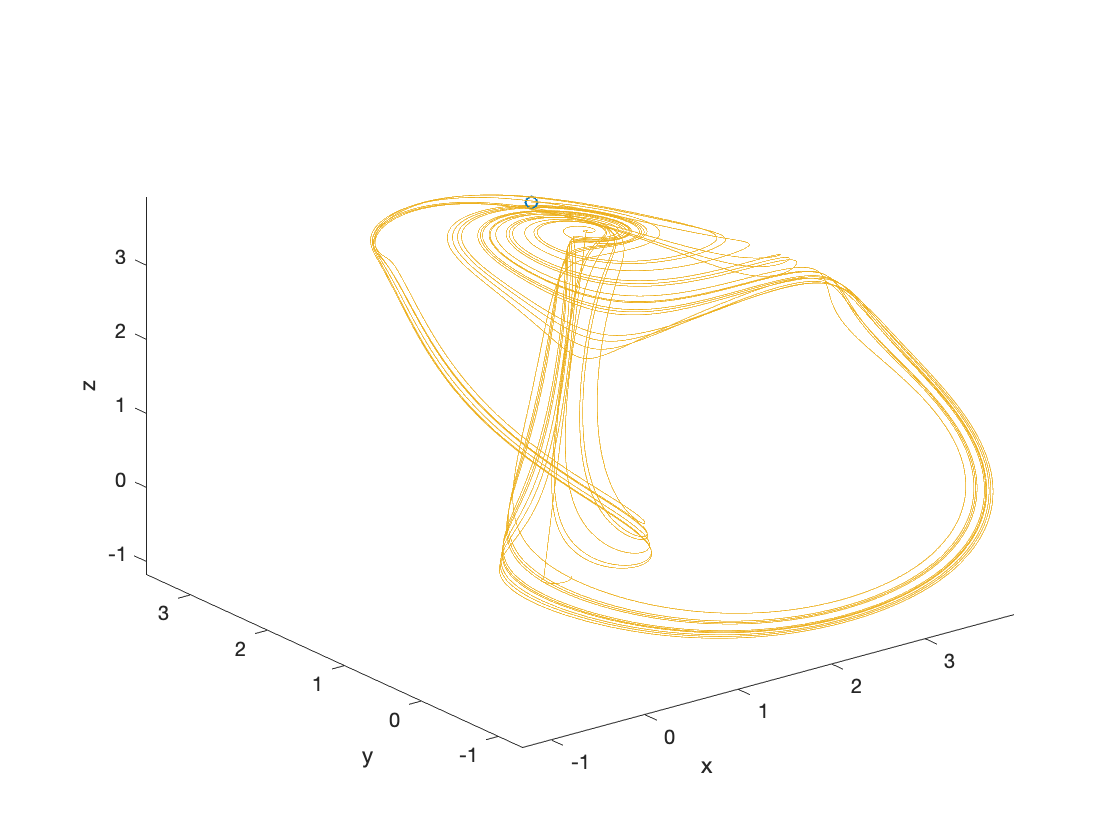


comet3(sol.y(:,1), sol.y(:,2), sol.y(:,3))

xlabel('x')
ylabel('y')
zlabel('z')

% Lorenz attractor
